Simulation 1 completed
Simulation 2 completed
Simulation 3 completed
Simulation 4 completed
Simulation 5 completed
Simulation 6 completed
Simulation 7 completed
Simulation 8 completed
Simulation 9 completed


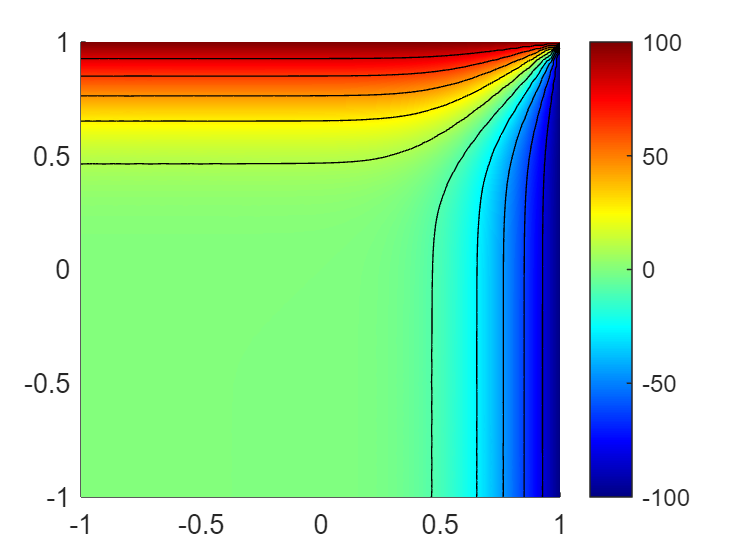

Simulation 10 completed


% Define parameters
numSimulations = 10;
imagePath = 'D:\AcadsSem7\BTP_One\MATLAB_Simulations\Learning_Parallel_Sims\ChatGpt5_rectImages\';

% Loop through simulations
for simIdx = 1:numSimulations
    % Run thermal simulation using the PDE Toolbox
    temperatureProfile = runThermalSimulation(simIdx);
    
    % Save temperature profile image
    saveTemperatureProfileImage(temperatureProfile, imagePath, simIdx);
    
    % Extract contours and save contour image
    %contourImage = extractContours(temperatureProfile);
    %saveContourImage(contourImage, imagePath, simIdx);
    
    % Display progress
    disp(['Simulation ', num2str(simIdx), ' completed']);
end


% Simulation function using PDE Toolbox

function temperatureProfile = runThermalSimulation(simIdx)
    % Create PDE model
    thermalmodel = createpde("thermal", "transient");
    geometryFromEdges(thermalmodel,@squareg);
    pdegplot(thermalmodel,"EdgeLabels","on")
    ylim([-1,1])
    axis equal
    
    thermalProperties(thermalmodel,"ThermalConductivity",0.1,...
                               "MassDensity",10,...
                               "SpecificHeat",1);

    thermalBC(thermalmodel,"Edge",1,"Temperature",simIdx * 10);
    thermalBC(thermalmodel,"Edge",2,"Temperature",-simIdx * 10);



    thermalIC(thermalmodel,0);
    generateMesh(thermalmodel);

    %pdemesh(thermalmodel)
    tlist = 0:0.5:5;
    temperatureProfile = solve(thermalmodel,tlist);
    pdeplot(thermalmodel,"XYData",temperatureProfile.Temperature(:,end), ...
                 "Contour","on",...
                 "ColorMap","jet")
end

% Image saving function for temperature profile
function saveTemperatureProfileImage(temperatureProfile, imagePath, simIdx)
    % Create a new figure
    figure;
    
    % Create a pdeplot for the 2D temperature data
    pdeplot(temperatureProfile.Mesh.Nodes, [], temperatureProfile.Mesh.Elements, 'XYData', temperatureProfile.Temperature(:,end),'ColorMap', 'jet');
    
    % Add title and labels
    title(['Temperature Profile (Simulation ', num2str(simIdx), ')']);
    xlabel('X');
    ylabel('Y');
    
    % Save the pdeplot as a PNG image
    tempImageName = sprintf('TemperatureProfile_%d.png', simIdx);
    tempImagePath = fullfile(imagePath, tempImageName);
    savePDEPlotAsPNG(gcf, tempImagePath);
    
    % Close the figure
    close(gcf);
end

% Function to save pdeplot as PNG
function savePDEPlotAsPNG(fig, imagePath)
    % Save the figure as PNG
    saveas(fig, imagePath, 'png');
end

% Function to extract contours
function contourImage = extractContours(temperatureProfile)
    % Create a new figure
    figure;
    
    % Create a pdecontour plot
    contourf(temperatureProfile.Mesh.Nodes, temperatureProfile.Mesh.Elements, 'XYData', temperatureProfile.Temperature);
    
    % Add title and labels
    title('Temperature Contours');
    xlabel('X');
    ylabel('Y');
    
    % Capture the contour plot
    contourImage = getframe(gcf);
    
    % Close the figure
    close(gcf);
end

% Function to save contour image
function saveContourImage(contourImage, imagePath, simIdx)
    % Save the contour image as a PNG
    contourImageName = sprintf('ContourImage_%d.png', simIdx);
    contourImagePath = fullfile(imagePath, contourImageName);
    imwrite(contourImage.cdata, contourImagePath);
end
